# Add and Query Group of Colleagues in Social Neighborhood

This example shows how to add a group of colleagues, stored as a directed graph, to a group of friends in a social neighborhood, stored as nodes and relationships in a Neo4j® database. The example then shows how to query the graph in the database by using the Cypher® query language, which enables you to create custom queries.

For details about the MATLAB® interface to Neo4j, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

Assume that you have graph data stored in a Neo4j database that represents the social neighborhood. This database has seven nodes and eight relationships. Each node has only one unique property key `name` with a value ranging from `User1` through `User7`. Each relationship has the type `knows`.

The local machine hosts the Neo4j database with the port number `7474`, user name `neo4j`, and password `matlab`. This figure provides a visual representation of the data in the database.

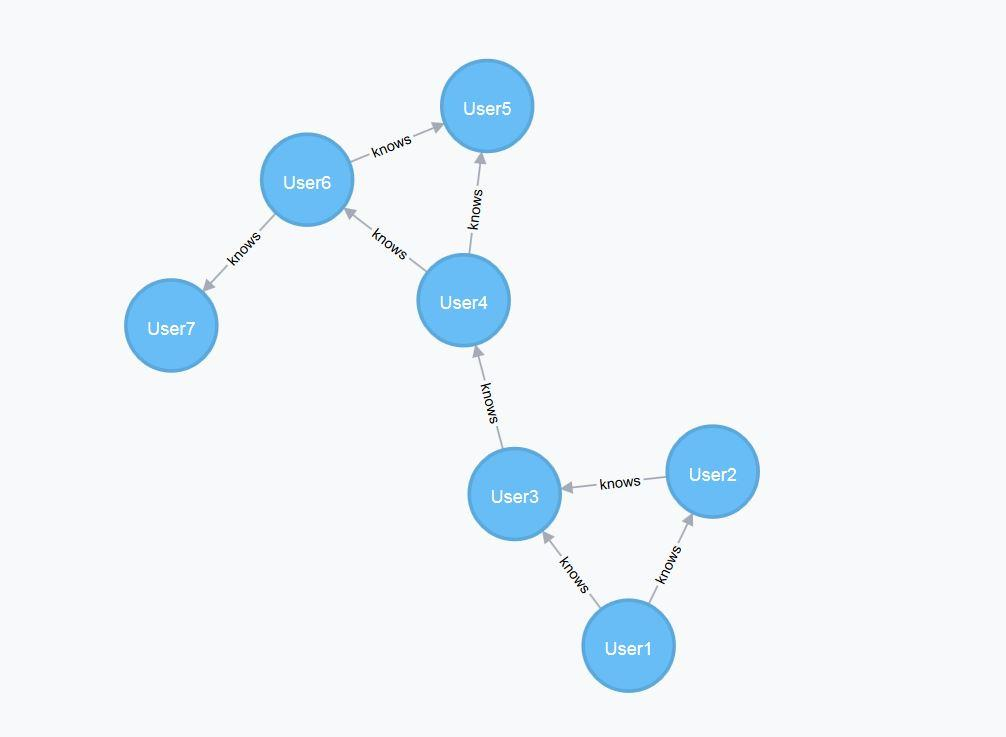

## Connect to Neo4j Database

Create a Neo4j connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Create Directed Graph

Define a group of four colleagues by creating a directed graph in MATLAB. Create a `digraph` object that has four nodes and three edges.

s = [1 1 1];
t = [2 3 4];
G = digraph(s,t);

Specify names for the nodes.

G.Nodes.name = {'User8';'User9';'User10';'User11'};

Plot the digraph to view the nodes and edges.

plot(G)

## Store Directed Graph in Neo4j Database

Store the directed graph as a Neo4j graph. Specify two labels for all nodes in the resulting Neo4j graph by using the `GlobalNodeLabel` name-value pair argument. Also, specify the type `works with` for all relationships in the resulting Neo4j graph by using the `GlobalRelationType` name-value pair argument.

graphinfo = storeDigraph(neo4jconn,G, ...
    'GlobalNodeLabel',{'Colleague','Person'}, ...
    'GlobalRelationType','works with');

Display the node labels of the first node in the graph.

graphinfo.Nodes.NodeLabels{1}

The result is a cell array of character vectors. Each character vector is a node label for the first node.

Display the relationships in the graph. 

graphinfo.Relations

`Relations` is a table that contains these variables:

- Start node identifier

- Relationship type

- End node identifier

- Relationship data

- `Neo4jRelation` object

## Connect Group of Colleagues to Friends in Existing Graph

Search for the nodes with the node label `Person` and the property key `name` set to the values `User7` and `User8` by using the Neo4j database connection.

nlabel = 'Person';
user7 = searchNode(neo4jconn,nlabel,'PropertyKey','name', ...
    'PropertyValue','User7');
user8 = searchNode(neo4jconn,nlabel,'PropertyKey','name', ...
    'PropertyValue','User8');

Add a relationship between the nodes `User7` and `User8` to connect the group of colleagues to the group of friends.

relationtype = 'knows';
relation = createRelation(neo4jconn,user7,user8,relationtype);

Display the resulting graph in the Neo4j database.

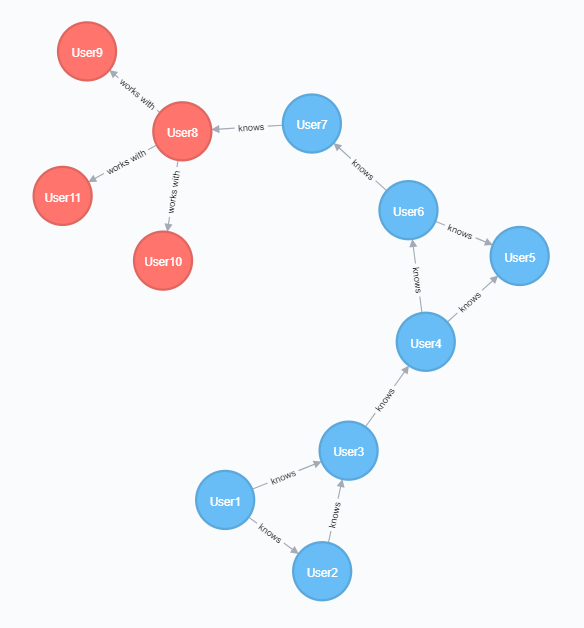

## Execute Cypher Query on Neo4j Database

Create a Cypher query to find the people who work with people `User7` knows. Display the names of those people.

query = ['MATCH (:Person {name: "User7"})-[:knows]->(:Person)-[:`works with`]' ...
    '->(potentialContact:Person) RETURN potentialContact.name'];
results = executeCypher(neo4jconn,query)

`User9`, `User10`, and `User11` all work with someone that `User7` knows. `User7` knows `User8`, who works with `User9`, `User10`, and `User11`.

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*